# GWO Algorithm

close all; clc; clear;
rand('seed',0);

### Parameters

wolf_num = 15;  % the wolf number
max_iter = 150;  % max iteration
dim = 30;       % the independent variable dimension
lb = -30*ones(1,dim);  % the lower bound
ub = 30*ones(1,dim);   % the upper bound
alpha_pos = zeros(1,dim); % the position of the wolf named "alpha" 
alpha_score = inf;        % the score of the wolf named "alpha"
beta_pos = zeros(1,dim);  % the position of the wolf named "beta" 
beta_score = inf;         % the score of the wolf named "beta"
delta_pos = zeros(1,dim); % the position of the wolf named "delta"
delta_score = inf;        % the score of the wolf named "delta"
convergence_curve = zeros(1,max_iter);  % the data of fitness curve 

### Main loop

count = 0;
position = init_pos(wolf_num,dim,ub,lb);  % init the position of the wolves
while count < max_iter
    for i = 1:wolf_num
        flag_ub = position(i,:) > ub;
        flag_lb = position(i,:) < lb;
        position(i,:) = position(i,:).*(~(flag_ub+flag_lb))+flag_ub.*ub+flag_lb.*lb;  % limit the position not exceed the bound
        fitness = f(position(i,:));   % get the fitness value
        if fitness < alpha_score
            alpha_score = fitness;
            alpha_pos = position(i,:);
        elseif fitness < beta_score
            beta_score = fitness;
            beta_pos = position(i,:);
        elseif fitness < delta_score
            delta_score = fitness;
            delta_pos = position(i,:);
        end
    end
    a = 2 - count*(2/max_iter);   % update a which which decrease from 2 to 0
    for i = 1:wolf_num
        for j = 1:dim
            alpha = update_pos(alpha_pos(j),position(i,j),a);
            beta = update_pos(beta_pos(j),position(i,j),a);
            delta = update_pos(delta_pos(j),position(i,j),a);
            position(i,j) = (alpha+beta+delta)/3;
        end
    end
    count = count + 1;
    convergence_curve(count) = alpha_score;
end

### Draw the results

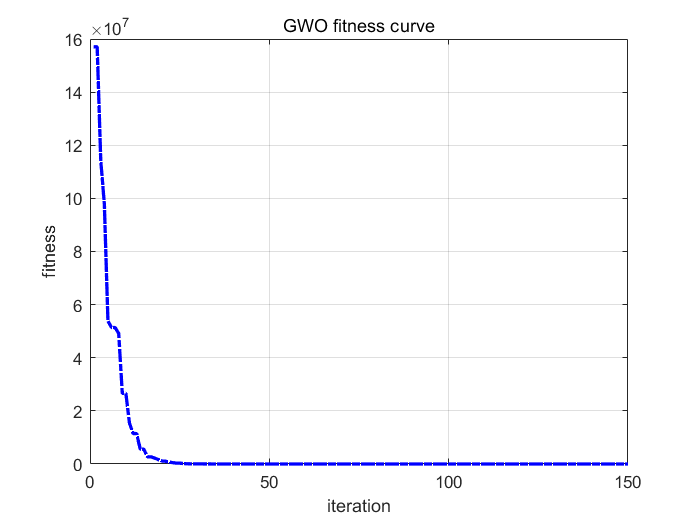

plot(1:max_iter,convergence_curve,'LineWidth',2,"LineStyle","-.","Color",'b')
xlabel('iteration'); ylabel('fitness'); title('GWO fitness curve');
grid on;

disp('The solution of GWO:'); disp(alpha_pos);

The solution of GWO:
  列 1 至 7

    0.1602   -0.0016   -0.0035   -0.0038   -0.0013   -0.0038   -0.0045

  列 8 至 14

    0.0102    0.0096   -0.0047    0.0097   -0.0032    0.0124    0.0101

  列 15 至 21

    0.0135    0.0109   -0.0037   -0.0036   -0.0035   -0.0039    0.0136

  列 22 至 28

    0.0113    0.0136    0.0113    0.0097   -0.0025   -0.0041    0.0099

  列 29 至 30

   -0.0036    0.0062



disp('The best fitness of GWO:'); disp(alpha_score);

The best fitness of GWO:
   28.7791



## Define the function:

#### Function to be optimized

function res = f(x)
% f_min : 0
dim = 30; sum = 0;
for i = 1:dim-1
    sum = sum + 100*(x(i+1)-x(i)^2)^2+(x(i)-1)^2;
end
res = sum;
end

#### Update the position

function res = update_pos(v1,v2,a)
A = 2*a*rand()-a;
C = 2*rand();
temp = abs(C*v1-v2);
res = v1 - A*temp;
end

#### Init the position of wolves

function position = init_pos(wolf_num,dim,ub,lb)
position = zeros(wolf_num,dim);
for i = 1:wolf_num
    for j = 1:dim
        position(i,j) = rand()*(ub(j)-lb(j)) + lb(j);
    end
end
end